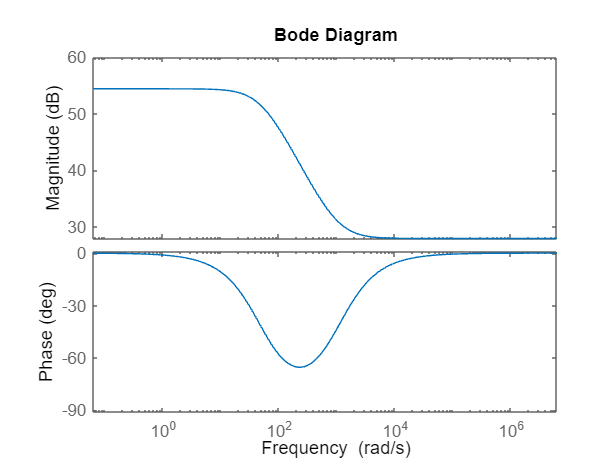

% Question 1a
R_s = 25; % Ohm
R_ct = 500; % Ohm
C_dl = 40e-6; % F
freqStart = 0.01*2*pi; % Hz
freqEnd = 1e6*2*pi; %Hz

R_par = (R_s*R_ct)/(R_s+R_ct);

numerator = [R_s, R_s/(R_par*C_dl)];
denominator = [1,1/(R_ct*C_dl)];

sys = tf(numerator, denominator);

bode(sys, {freqStart, freqEnd})

% (TODO - Z_warburg) Question 1b
R_s = 25; % Ohm
R_ct = 500; % Ohm
C_dl = 40e-6; % F
warCoef = 150; % Ohm/s

freqStart = 0.01*2*pi; % Hz
freqEnd = 1e6*2*pi; %Hz

R_par = (R_s*R_ct)/(R_s+R_ct);

numerator = [R_s, R_s/(R_par*C_dl)];
denominator = [1,1/(R_ct*C_dl)];

sys = tf(numerator, denominator);

bode(sys, {freqStart, freqEnd})

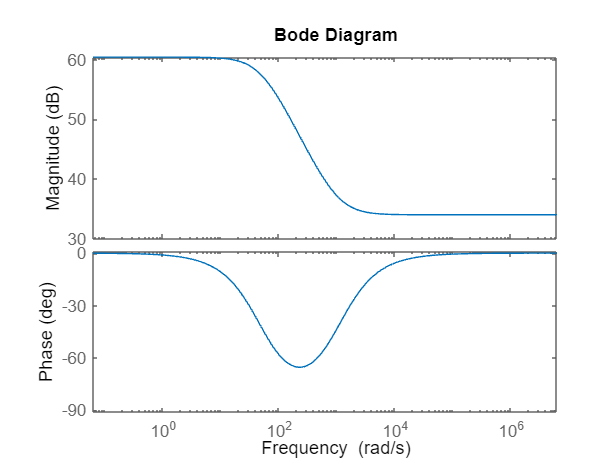

% Question 1c
R_s = 50; % Ohm
R_ct = 1000; % Ohm
C_dl = 20e-6; % F
freqStart = 0.01*2*pi; % Hz
freqEnd = 1e6*2*pi; %Hz

R_par = (R_s*R_ct)/(R_s+R_ct);

numerator = [R_s, R_s/(R_par*C_dl)];
denominator = [1,1/(R_ct*C_dl)];

sys = tf(numerator, denominator);

bode(sys, {freqStart, freqEnd})

% (TODO - Question 1b) Question 1d

% (TODO - Consider material implications) Question 2a
R_s = 1900; % Ohm
R_ct = 15000; % Ohm
C_dl = 220e-9; % F
freqStart = 0.01*2*pi; % Hz
freqEnd = 1e6*2*pi; %Hz

R_par = (R_s*R_ct)/(R_s+R_ct);

numerator = [R_s, R_s/(R_par*C_dl)];
denominator = [1,1/(R_ct*C_dl)];

sys = tf(numerator, denominator);


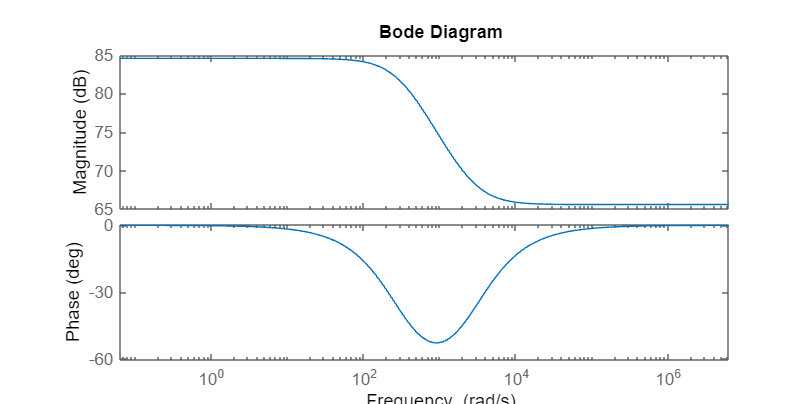

% (TODO - Run once 2a is complete) Question 2b
bode(sys, {freqStart, freqEnd})

% (Once Question 2a is complete) Question 2c

% Question 3a

% Prior to reading in the table, I removed all of the diagnostic
% information from above the data.
pt_Data = readtable('be260-hw2-2020-fall-cv-platinum.csv');

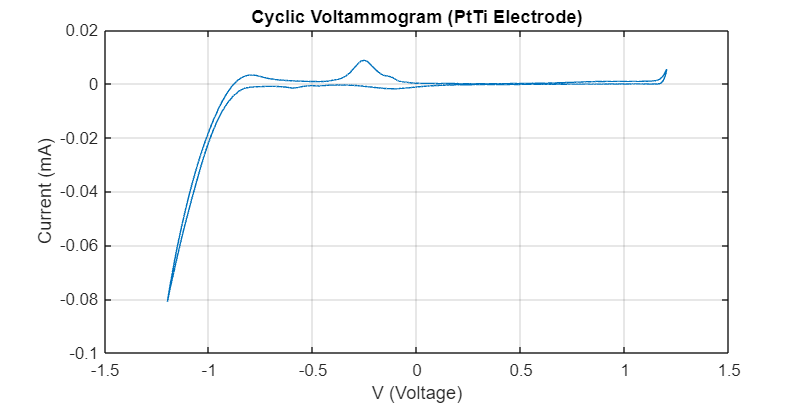

I = table2array(pt_Data(:,'x_I__mA'));
V = table2array(pt_Data(:,'Ewe_V'));

plot(V,I)
grid on;
xlabel('V (Voltage)');
ylabel('Current (mA)');
title("Cyclic Voltammogram (PtTi Electrode)");

Q = trapz(V,I) % Computes the area under the curve

Q = 0.0053

% The overall charge Q corresponding to its opening is 0.0053 mC

% (TODO - Comp w Q2 once finished) Question 3b

ptElectrodeEffectiveArea = Q / 210 % (mC) / (mC cm^-2) = cm^2

ptElectrodeEffectiveArea = 2.5406e-05

% Using Q = 0.0053 from 3(a), the effective area of the electrode would be
% 2.54e-5.

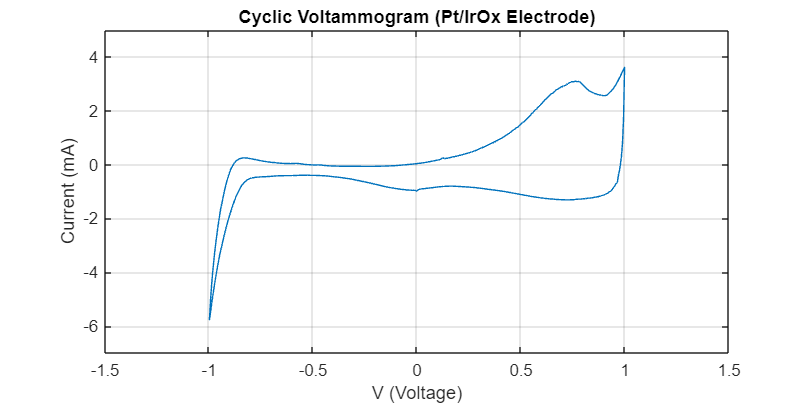

% (TODO - Finish end discussion) Question 3c

% Prior to reading the data, I deleted the all sheets except for the one
% titled Ir_Pt_IV
ptIrox_Data = readtable('be260-hw2-2022-fall-cv-irox.xlsx');
I = table2array(ptIrox_Data(:,"Column2"));
V = table2array(ptIrox_Data(:,"Column1"));

plot(V,I)
grid on;
xlabel('V (Voltage)'); xlim([-1.5 1.5]);
ylabel('Current (mA)'); ylim([-7 5]);
title("Cyclic Voltammogram (Pt/IrOx Electrode)");

Q = trapz(V,I) % Computes the area under the curve

Q = 3.2775

ptIrOxElectrodeEffectiveArea = Q / 210 % (mC) / (mC cm^-2) = cm^2

ptIrOxElectrodeEffectiveArea = 0.0156

% Using Q = 3.2775 from above, the effective area of the electrode would be
% 0.0156.

% The overall charge and therefore the effective area of the electrode are
% both larger for the IrOx-coated Pt electrode than the Pt electrode alone. 
% This makes sense because an increase in surface area directly correlates
% with an increased capacitance. However, 

% (TODO) Question 4a

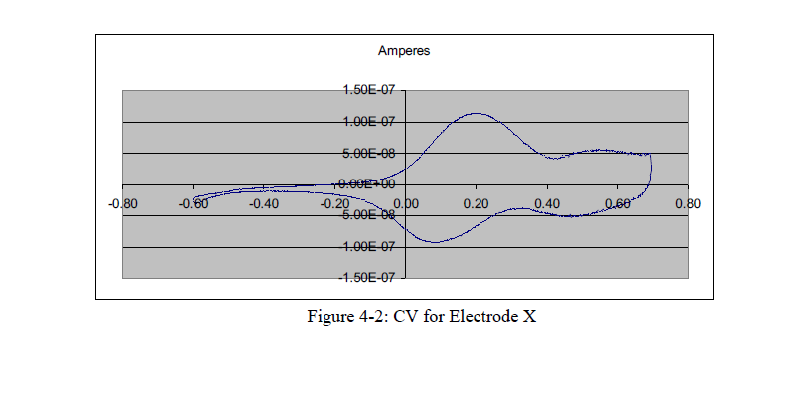

% Question 4b
imshow('Screenshot 2022-10-15 123542.png')

% The water window is the range of potentials applied to generate the CV
% Voltammogram. In the above figure, the water window appears to be roughly
% [-0.6V 0.68V].

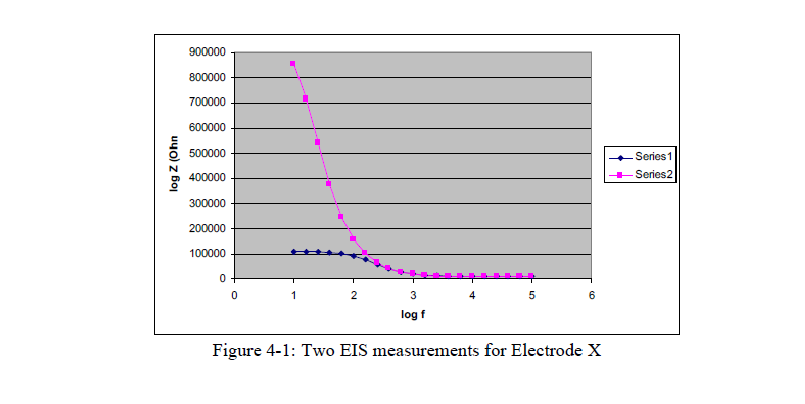

% Question 4c
imshow("Screenshot 2022-10-15 130721.png")

% The pole of this figure defines the value R_S + R_{ct} and the zero of
% this figure defines the value R_S. In this case, the pole is at roughly
% log f = 2 and the zero is at roughly log f = 3.5. Therefore, R_S ~= 10
% kOhm and R_S + R_{ct} = 100 kOhm, so R_{ct} = 90 kOhm. The pole of 10e2
% equals the expression 1/(R_{ct}*C_{dl}). We know R_{ct}, so the only
% unknown is C_{dl}, which we can solve for:

% f = 1/(R_{ct}*C_{dl})
% C_{dl} = 1/(2pif*R_{ct})
% C_{dl} = 1/(2pi*(10^2)*(9*10^4))
C_dl = 1/(2*pi*9e6) % F

C_dl = 1.7684e-08

% Therefore, R_{ct} = 90 kOhm/cm^2, R_S = 10 kOhm, and C_{dl} = 1.7684e-8.

% Question 4d
R_s = 1000; % Ohm
R_ct = 90000; % Ohm
C_dl = 1.7684e-8; % F

R_par = (R_s*R_ct)/(R_s+R_ct);

numerator = [R_s, R_s/(R_par*C_dl)];
denominator = [1,1/(R_ct*C_dl)];

sys = tf(numerator, denominator);

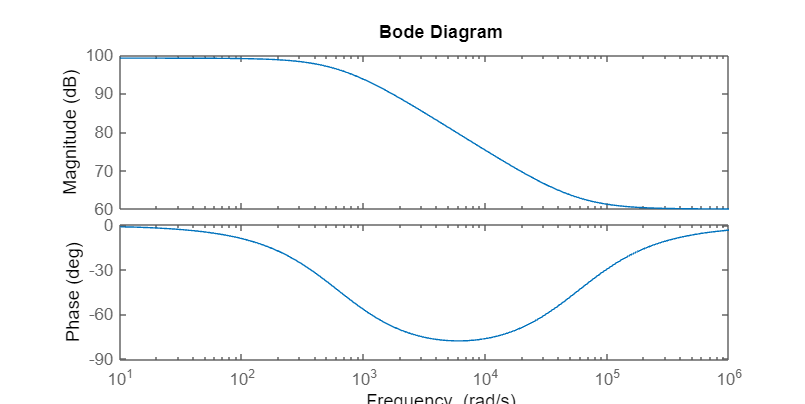

% Question 4e
bode(sys)

% (TODO - (4) and (5) + address roughness?) Question 5a

% Definition of given parameters
rho = 560; % Ohm*s (Retina Tissue Resitivity)
r_elec = 50e-6; % m (Radius of microelectrode)
C_dl_orig = 54.5e-6; %F/cm^2 (Original double layer capacitance)
R_ct_orig = 5.1e4; % m^-2 (Original charge transfer resistance)

roughness_factor = 40;

% Since the electrode is circular and R_s ignores roughness, R_s can be found 
% via the equation: R_S = rho / 4r
R_S_a = rho/(4*r_elec) % Ohm

R_S_a = 2800000

% Since C_dl is directly proportional to the electrode surface area,
% increasing the roughness of the area by a factor of 40x would also
% increase C_dl by a factor of 40, so
C_dl_a = C_dl_orig*40

C_dl_a = 0.0022

% Since R_ct is inversely proportional to the electrode surface area,
% increasing the roughness of the area by a factor of 40x would
% decrease R_ct by a factor of 40, so
R_ct_a = R_ct_orig/40

R_ct_a = 1275

% Question 5b

% Since R_S is independent of surface area, it remains the same:
R_S_b = R_S_a

R_S_b = 2800000

% Since C_dl is directly proportional to the electrode surface area,
% decreasing the surface area by 10% would decrease C_dl by 10%:
C_dl_b = C_dl_a*0.9

C_dl_b = 0.0020

% Since R_ct is inversely proportional to the electrode surface area,
% decreasing the surface area by 10% would increase C_dl by 10%:
R_ct_b = R_ct_a*1.1

R_ct_b = 1.4025e+03

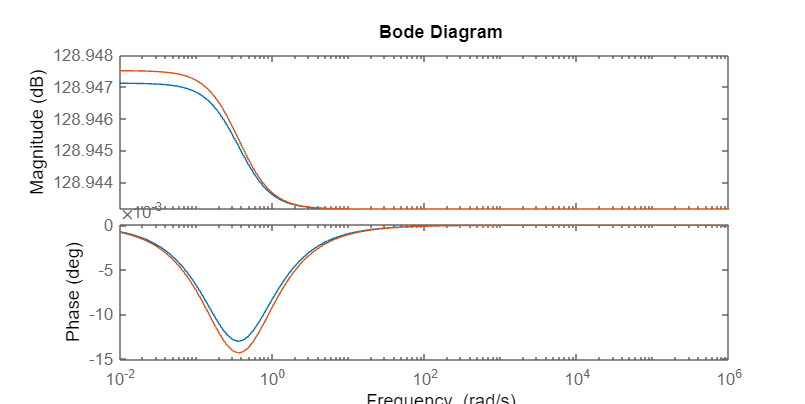

% Question 5c

R_par_a = (R_S_a*R_ct_a)/(R_S_a+R_ct_a);

numerator_a = [R_S_a, R_S_a/(R_par_a*C_dl_a)];
denominator_a = [1,1/(R_ct_a*C_dl_a)];

sys_a = tf(numerator_a, denominator_a);

R_par_b = (R_S_b*R_ct_b)/(R_S_b+R_ct_b);

numerator_b = [R_S_b, R_S_b/(R_par_b*C_dl_b)];
denominator_b = [1,1/(R_ct_b*C_dl_b)];

sys_b = tf(numerator_b, denominator_b);

bode(sys_a,sys_b,{1e-2 1e6})